# Solving Differential Equations(ODE)

clear all;
close all;

% 1. first order ODE
% example 1 : Linear ODE
syms t y(t)
dy = diff(y , t);
ode01 = dy + 0.5*y == 5*sin(2*t)

$$ode01(t) = \frac{\partial }{\partial t}y\left(t\right)+\frac{y\left(t\right)}{2}=5\,\sin\left(2\,t\right)$$

% Question: Analytic solution
sol01 = dsolve(ode01) % general solution

$$sol01 = C_{1}\,{\mathrm{e}}^{-\frac{t}{2}}-\frac{10\,\sqrt{17}\,\cos\left(2\,t+\mathrm{atan}\left(\frac{1}{4}\right)\right)}{17}$$

% displaying solution
% way 1: by a particular solution
incond01 = y(0) == 2

$$incond01 = y\left(0\right)=2$$

psol01 = dsolve(ode01, incond01)

$$psol01 = \frac{74\,{\mathrm{e}}^{-\frac{t}{2}}}{17}-\frac{10\,\sqrt{17}\,\cos\left(2\,t+\mathrm{atan}\left(\frac{1}{4}\right)\right)}{17}$$

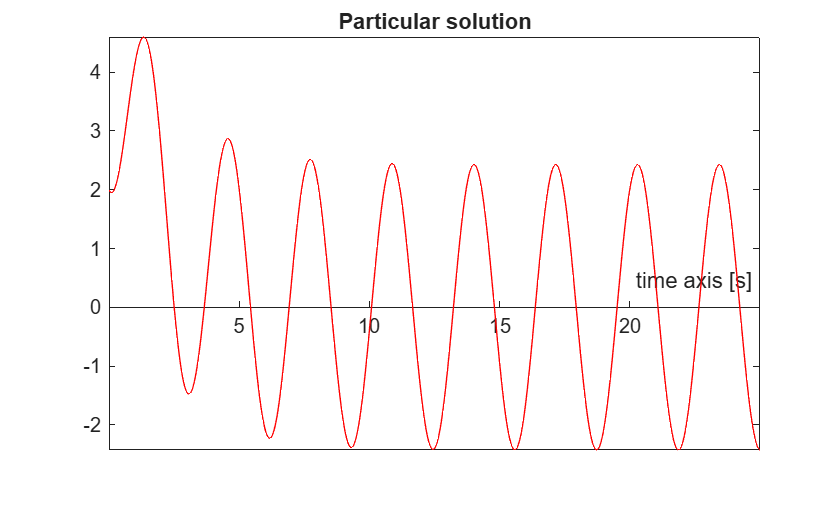


fplot(psol01, [0 25], 'r')

ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
xlabel("time axis [s]")
title("Particular solution")

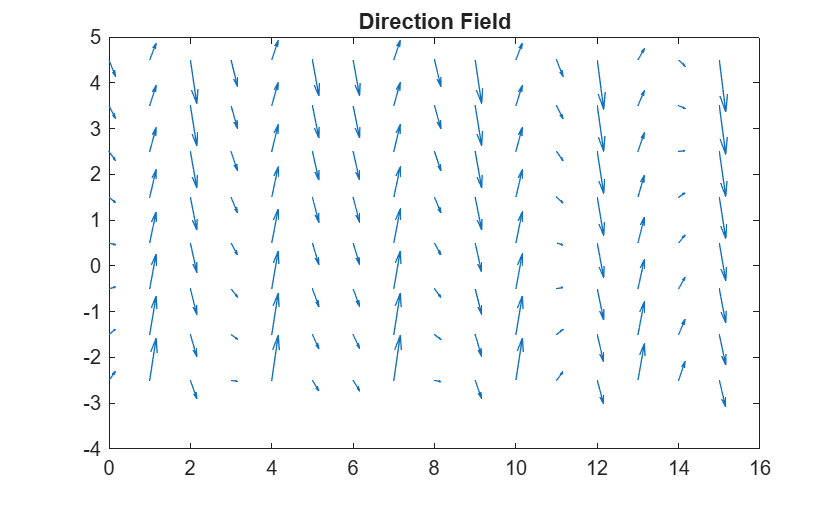


%
% way 2. DIRECTION FIELD
% constructing a system of grid points
figure
h = 1;
X = 0:h:15;
Y = -2.5:h:4.5;
[U, V] = meshgrid(X,Y);
D = -0.5*V + 5*sin(2*U);
E = ones(size(D));
quiver(U, V, E, D)
title('Direction Field')

% 2nd order linear ODE
d2y = diff(y,t,2);
ode02 = d2y + 5*dy +6*y ==0;
sol02 = dsolve(ode02) % general solution

$$sol02 = C_{1}\,{\mathrm{e}}^{-3\,t}+C_{2}\,{\mathrm{e}}^{-2\,t}$$


Incond01 = y(0) == 0;
Incond02 = dy(0) == 1;

psol02 = dsolve(ode02, Incond01, Incond02)

$$psol02 = {\mathrm{e}}^{-3\,t}\,\left({\mathrm{e}}^{t}-1\right)$$

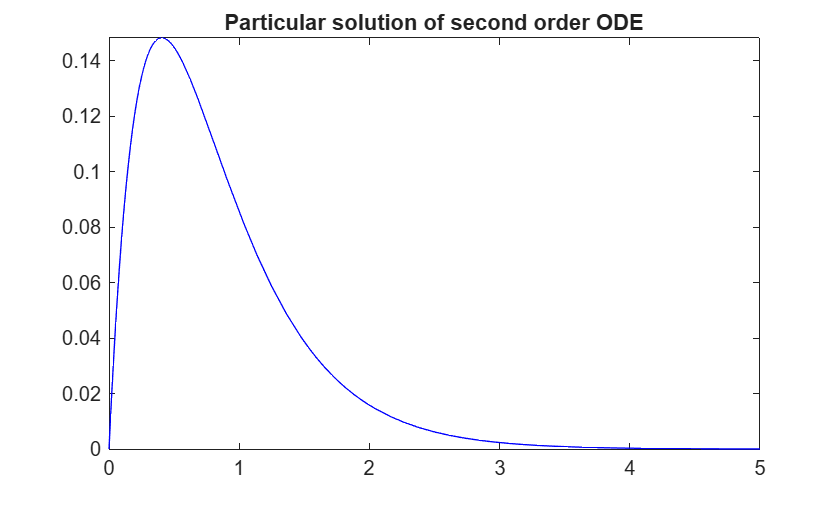


% displaying
fplot(psol02, [0,5], 'b')
title("Particular solution of second order ODE")

% For a second order equation, the direction field is not defined